clc
% clear all

Leyendo la base de datos, se ve que contiene 252 filas y 753 columnas, las filas corresponden a todos los sujetos, y las colunmas a las variables medidas sobre las señales de voz

data = readtable("pd_speech.csv");
summary(data);

Variables:

    rownames: 252×1 double

        Values:

            Min            1  
            Median     126.5  
            Max          252  

    gender: 252×1 double

        Values:

            Min          0    
            Median       1    
            Max          1    

    PPE: 252×1 double

        Values:

            Min       0.31435 
            Median    0.80204 
            Max       0.86993 

    DFA: 252×1 double

        Values:

            Min       0.55597 
            Median    0.69941 
            Max       0.85111 

    RPDE: 252×1 double

        Values:

            Min       0.19385 
            Median    0.48312 
            Max       0.82648 

    meanPeriodPulses: 252×1 double

        Values:

            Min       0.0032726
            Median    0.0060918
            Max        0.011608

    stdDevPeriodPulses: 252×1 double

  

Conteo de hombres y mujeres por cada grupo de Parkinson y Control:

data_gender=groupsummary(data,["gender","class"])

data_gender = 4×3 table
    gender       class       GroupCount
    ______    ___________    __________

      0       {'PD'     }        81    
      0       {'control'}        41    
      1       {'PD'     }       107    
      1       {'control'}        23    


Selección de las variables de interés. Esta es la tabla de datos que usarán para desarrollar el proyecto:

x=data(:,["gender" "class" "PPE" "DFA" "RPDE"])

x = 252×5 table
    gender       class         PPE        DFA       RPDE  
    ______    ___________    _______    _______    _______

      1       {'PD'     }    0.82339    0.69637    0.56725
      0       {'PD'     }    0.41564    0.79399    0.59245
      1       {'PD'     }    0.80197    0.61997    0.52056
      0       {'PD'     }    0.82871     0.6261    0.53718
      0       {'PD'     }    0.83129     0.7794    0.72672
      1       {'PD'     }    0.82252    0.62208    0.35766
      1       {'PD'     }    0.80003    0.66728    0.39158
      1       {'PD'     }    0.52919    0.77486    0.71268
      1       {'PD'     }    0.81879     0.6424    0.50103
      1       {'PD'     }     0.8462    0.60863    0.43147
      1       {'PD'     }    0.48983    0.65193      0.638
      1       {'control'}    0.82284    0.6641

Con la tarea de "Compute by Group" se pueden obtener tablas de datos estadísticos (Computations stats) de varias variables (compute on), incluso agrupadas según género y clase (Group by).

**1) Utilice la tarea en tiempo real de Matlab “compute by group” para calcular múltiples  estadísticas descriptivas de la PPE, DFA y RPDE (media, max, min, std, var, datos  perdidos, etc) por cada grupo de datos: control_hombre, control_mujer, EP_hombre,  EP_mujer**

% Compute group summary
BD = groupsummary(x,["gender","class"],["mean","median","mode","max", ...
    "min","std","var","nummissing"],vartype("numeric"));
BD.GroupCount = []

BD = 4×34 table
    gender       class       mean_gender    median_gender    mode_gender    max_gender    min_gender    std_gender    var_gender    nummissing_gender    mean_PPE    median_PPE    mode_PPE    max_PPE    min_PPE    std_PPE      var_PPE     nummissing_PPE    mean_DFA    median_DFA    mode_DFA    max_DFA    min_DFA    std_DFA      var_DFA     nummissing_DFA    mean_RPDE    median_RPDE    mode_RPDE    max_RPDE    min_RPDE    std_RPDE    

**2) Realice un análisis exploratorio de los datos dividiendo los datos según los grupos control y EP, y subdividiendo según el género así:**

**a. Realice gráficos de barras para mostrar la distribución de los datos (control y EP) vs género**

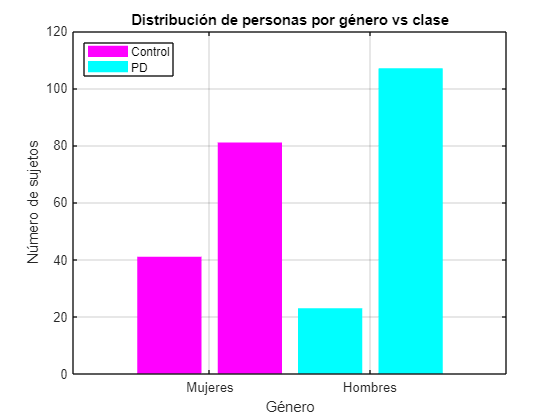

% Filtrar los datos por clase y género
controlFemenino = data_gender{(data_gender.gender == 0) & (data_gender.class == "control"), 'GroupCount'};
PDfemenino = data_gender{(data_gender.gender == 0) & (data_gender.class == "PD"), 'GroupCount'};
controlMasculino = data_gender{(data_gender.gender == 1) & (data_gender.class == "control"), 'GroupCount'};
PDmasculino = data_gender{(data_gender.gender == 1) & (data_gender.class == "PD"), 'GroupCount'};

% Gráfico de barras
bar([1, 2], [controlFemenino, PDfemenino], 'FaceColor', 'magenta', 'EdgeColor', 'none'); % Mujeres en rosado
hold on;
bar([3, 4], [controlMasculino, PDmasculino], 'FaceColor', 'cyan', 'EdgeColor', 'none'); % Hombres en cyan
hold off;

xticks([1.5 3.5]);
xticklabels({'Mujeres', 'Hombres'});
xlabel('Género');
ylabel('Número de sujetos');
title('Distribución de personas por género vs clase');

legend({'Control', 'PD'}, 'Location', 'northwest');

grid on;

b. Realice los histogramas de PPE, DFA, RPDE por grupos de muestras. Además, obtenga y grafique la PDF.

variables = {'PPE', 'DFA', 'RPDE'};
generos = unique(data.gender);

figure;
for v = 1:length(variables)
    varName = variables{v};
    for g = 1:length(generos)
        subplot(length(variables), length(generos), (v-1)*length(generos)+g);
        hold on;
        
        % Green: contro, Blue: PD
        colors = {'green', 'blue'};
        
        h = zeros(1, length(clases));
        
        for c = 1:length(clases)
            % Filtrar datos por género y clase
            filteredData = data(data.gender == generos(g) & strcmp(data.class, clases(c)), :);
            
            % Histograma
            h(c) = histogram(filteredData.(varName), 'Normalization', 'pdf', 'FaceColor', colors{c}, 'FaceAlpha', 0.5);
            
            % PDF
            pd = fitdist(filteredData.(varName),'Kernel','Kernel','normal');
            x_values = linspace(min(filteredData.(varName)), max(filteredData.(varName)), 100);
            y_values = pdf(pd, x_values);
            plot(x_values, y_values, 'LineWidth', 2, 'Color', colors{c});
        end
        
        % Título
        genderStr = 'Mujeres';
        if generos(g) == 1
            genderStr = 'Hombres';
        end

        title([genderStr ', ' varName]);
        xlabel(varName);
        ylabel('Densidad');
        hold off;
    end
end

legend(h, {'Control', 'PD'}, 'Location', 'northwest');

c. Obtenga los boxplot de las variables PPE, DFA y RPDE para las cuatro muestras.

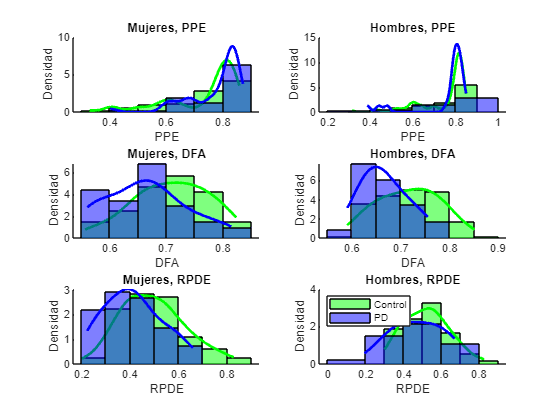

variables = {'PPE', 'DFA', 'RPDE'};

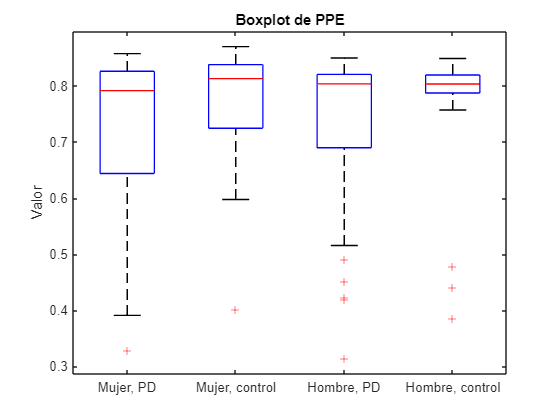

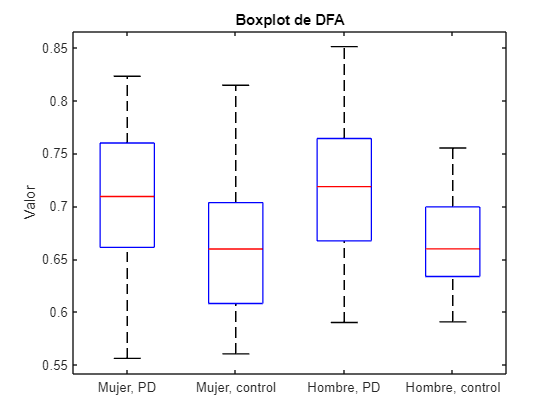

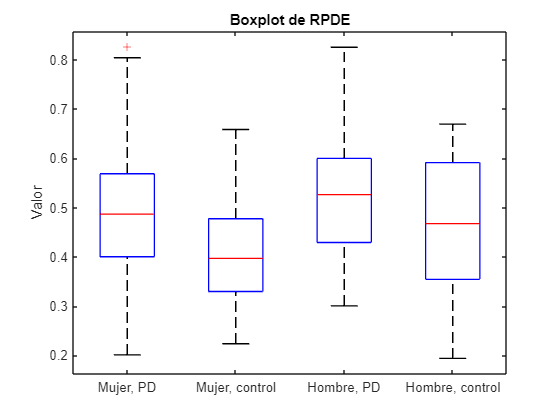

generos = [0, 0, 1, 1]; % Sin esto no funciona
clases = {'PD', 'control', 'PD', 'control'}; % Sin esto tampoco
groupLabels = {'Mujer, PD', 'Mujer, control', 'Hombre, PD', 'Hombre, control'};

for v = 1:length(variables)
    varName = variables{v};
    figure;
    boxData = [];
    groupVector = [];
    
    % Filtrado de datos
    for i = 1:length(groupLabels)
        % Hace un arreglo que coincidan con generos(i) y clases(i)
        filteredData = data(data.gender == generos(i) & strcmp(data.class, clases(i)), :);
        boxData = [boxData; filteredData.(varName)];
        % Crea un vector del mismo tamaño de filteredData.(varName), lleno de i
        groupVector = [groupVector; i*ones(size(filteredData.(varName)))];
    end
    
    % Boxplot
    boxplot(boxData, groupVector, 'Labels', groupLabels);
    title(['Boxplot de ' varName]);
    ylabel('Valor');
end